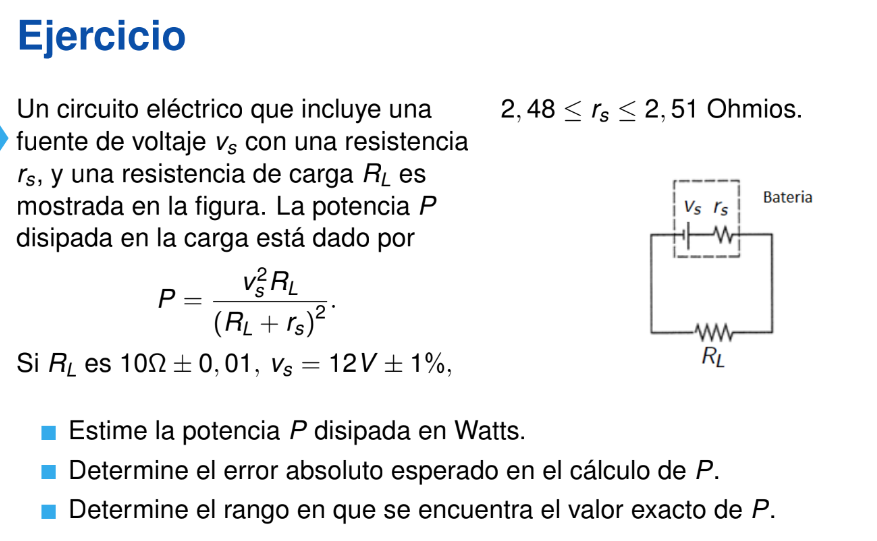

syms v R r 

%Funcion P
P = @(v,R,r) (v^(2) * R)/(R + r)^2;

%Valores de R v r
v_val = 12;
R_val = 10;
r_val = (2.51 - 2.48) / 2 + 2.48;

%Error absoluto
eav = v_val * 0.01;
eaR = R_val * 0.01;
ear = (2.51 - 2.48) / 2;

%Derivadas
dP_dv = matlabFunction(diff(P,v));
dP_dR = matlabFunction(diff(P,R));
dP_dr = matlabFunction(diff(P,r));

%Valor Absoluto de P
eaP = abs(dP_dv(R_val,r_val,v_val)) * eav + abs(dP_dR(R_val,r_val,v_val)) * eaR + abs(dP_dr(R_val,r_val,v_val)) * ear

eaP = 0.2620

%Valor Exacto
valorExacto = P(v_val,R_val,r_val)

valorExacto = 9.2234

%Valores minimo y maximo
valorMaximo = valorExacto + eaP

valorMaximo = 9.4854

valorMinimo = valorMaximo - eaP

valorMinimo = 9.2234